# Investigating algorithmic complexity of asynchronous and synchronous algorithms

effects of collapse cordon

## Generate buildings

fixed height pattern

### Parameters

Neq = 20; % <Neq> - The number of earthquakes/simulations.
hmin = 5;
hmax = 200;
Rhr = 1.5; % the ratio of cordon radius to height.
d = 100; % adjacent distance
RTperM = 0.1; % repair time (days) per meter of height.
P = 0.2; % <P> - Probability of needing repair.
n_range = 10:10:100; % <n> - The total number of buidings is n x n.
nPattern = 10;

### Code

f = waitbar(0,'Please wait...');
HPattern = HeightExp(hmin,hmax,nPattern); 
for n=n_range
    waitbar((n-min(n_range))/(max(n_range)-min(n_range)),f,'Please wait...');
    [DepCell,IRTsCell,FSCell] = BldPortGen(n,Neq,P,hmin,hmax,Rhr,d,RTperM, ...
        HPattern);
    CreateBldFootprint(n,d,HPattern,['tempdata/Bld_Footprint_n',num2str(n),'_P',num2str(P),'.csv']);
    [status,msg] = mkdir('tempdata');
    save(['tempdata/Data_Bld_Pattern_n',num2str(n),'_P',num2str(P),'.mat'], ...
        'DepCell','IRTsCell','FSCell');
end
close(f)

### 3D view

#### Cordon area

Parameters

n = 10;
iBld = 32; % the building that is plotted

Code

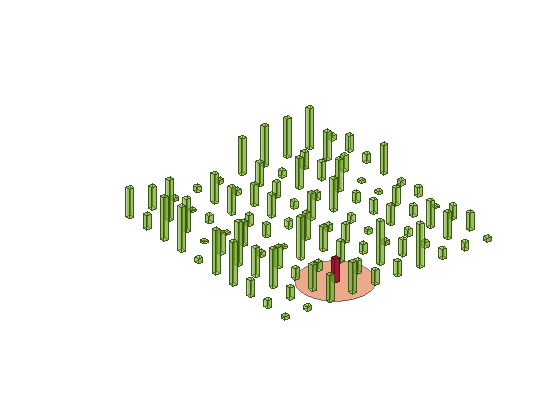

filename = ['tempdata/Bld_Footprint_n',num2str(n),'_P',num2str(P),'.csv'];
facecolor = [0.4660 0.6740 0.1880]; % green
facealpha = 0.5;
plot_bld_3D(filename,facecolor,facealpha,iBld,Rhr);

legend('off')

#### Collapse states

Parameters

n = 10;

Code

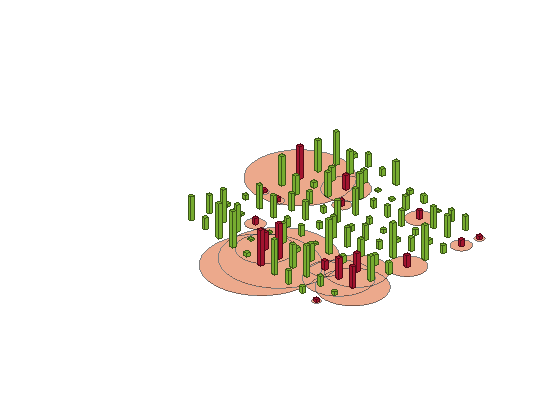

Bldfilename = ['tempdata/Bld_Footprint_n',num2str(n),'_P',num2str(P),'.csv'];
EQfile = ['tempdata/Data_Bld_Pattern_n',num2str(n),'_P',num2str(P),'.mat'];
plot_bldCollapse_3D(Bldfilename,EQfile,Rhr);

## Run simulation

to estimate time cost

Parameters:

DeltaT_range = [1,5/4,5/3,5/2];
MaxT = 200;

Independent

f = waitbar(0,'Please wait...');
for it = 1:numel(DeltaT_range)
    waitbar(it/numel(DeltaT_range),f,'Please wait...');
    DeltaT = DeltaT_range(it);
    for IfAsyn = [1,0]
        SynORAsy = {'Syn','Asy'}; 
        SynORAsy = SynORAsy{IfAsyn+1};
        for i=1:numel(n_range)
            load(['tempdata/Data_Bld_Pattern_n',num2str(n_range(i)),'_P',num2str(P),'.mat']);
            if IfAsyn
                [t1,FShistCell] = TicTocRecoverySimCordonAsy(cell(size(FSCell)),IRTsCell,FSCell);
            else
                [t1,FShistCell] = TicTocRecoverySimCordonSyn(DeltaT,MaxT,cell(size(FSCell)),IRTsCell,FSCell);
            end
            save(['tempdata/TimeCost_Cordon_Pattern_Independent_',SynORAsy,'_n',num2str(n_range(i)), ...
                '_dt',num2str(DeltaT),'_P',num2str(P),'.mat'], ...
                't1','FShistCell');
        end
    end
end
close(f)

Interdependent

% Run Asynchronous simulations before synchromous ones
f = waitbar(0,'Please wait...');
for it = 1:numel(DeltaT_range)
    waitbar(it/numel(DeltaT_range),f,'Please wait...');
    DeltaT = DeltaT_range(it);
    for IfAsyn = [1,0]
        SynORAsy = {'Syn','Asy'}; 
        SynORAsy = SynORAsy{IfAsyn+1};
        for i=1:numel(n_range)
            load(['tempdata/Data_Bld_Pattern_n',num2str(n_range(i)),'_P',num2str(P),'.mat']);
            if IfAsyn
                [t1,FShistCell] = TicTocRecoverySimCordonAsy(DepCell,IRTsCell,FSCell);
            else
                [t1,FShistCell] = TicTocRecoverySimCordonSyn(DeltaT,MaxT,DepCell,IRTsCell,FSCell);
            end
            save(['tempdata/TimeCost_Cordon_Pattern_',SynORAsy,'_n',num2str(n_range(i)), ...
                '_dt',num2str(DeltaT),'_P',num2str(P),'.mat'], ...
                't1','FShistCell');
        end
    end
end
close(f)

## Figure: function recovery curves

The situation that is plotted

n=20;
DeltaT = 1;

code:

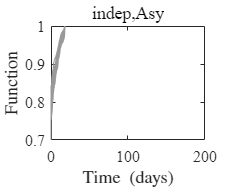

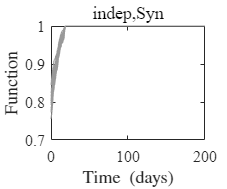

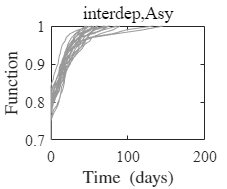

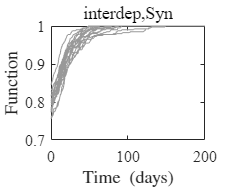

for k = ["indep","interdep"]
    for IfAsyn = [1,0]
        SynORAsy = {'Syn','Asy'}; 
        SynORAsy = SynORAsy{IfAsyn+1}; 
        if strcmp(k,"indep")
            load(['tempdata/TimeCost_Cordon_Pattern_Independent_',SynORAsy,'_n',num2str(n), ...
                '_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
        else
            load(['tempdata/TimeCost_Cordon_Pattern_',SynORAsy,'_n',num2str(n), ...
                '_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
        end
        if IfAsyn
            figure 
            hold on
            for i_eq = 1:numel(FShistCell)
                x = FShistCell{i_eq}(1,:);
                y = FShistCell{i_eq}(2,:);
                plot_function_recovery(x,y);
            end
        else
            figure
            x = (1:size(FShistCell{1},2))-1;
            x = x.*DeltaT;
            y = zeros(numel(FShistCell),size(x,2));
            for i=1:numel(FShistCell)
                y(i,:) = sum((FShistCell{i}-1),1)./size(FShistCell{i},1);
            end
            plot_function_recovery(x,y);
        end
        
        title(strcat(k,', ',SynORAsy));
        xlim([0 200]);
        ylim([0.7 1]);
    end
end

## Figure: computer time VS Number of buildings

Code

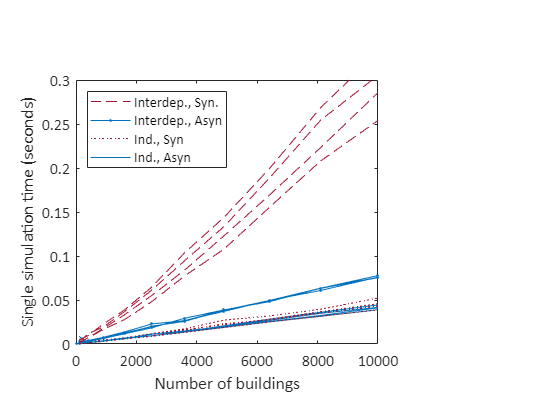

SynORAsy = {'Asy','Syn'}; 
x = n_range.^2;

figure
hold on

y = [];
for it = 1:numel(DeltaT_range)
    DeltaT = DeltaT_range(it);
    for j=1:2 % Asy OR Syn
        for i=1:numel(n_range)
            load(['tempdata/TimeCost_Cordon_Pattern_Independent_',SynORAsy{j}, ...
                '_n',num2str(n_range(i)),'_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
            y0(i) = t1;
            load(['tempdata/TimeCost_Cordon_Pattern_',SynORAsy{j}, ...
                '_n',num2str(n_range(i)),'_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
            y(i) = t1;
        end
        p0 = plot(x,y0);
        p = plot(x,y);
        if j==1 % Asy
            p.Marker = '.';
            p.Color = [0 0.4470 0.7410];
            p0.Color = [0 0.4470 0.7410];
        else
            p.Color = [0.6350 0.0780 0.1840];
            p0.Color = [0.6350 0.0780 0.1840];
            p0.LineStyle = ':';
            p.LineStyle = '--';
        end
    end
end

box on
ylim([0,0.3]);
ax = gca; 
ax.FontSize = 12;
ax.FontName = 'Calibri';
ax.Units = "centimeters";
ax.Position = [2 2 8 7];
ax.PositionConstraint = "innerposition";
xlabel('Number of buildings');
ylabel('Single simulation time (seconds)');

% Placeholder
ph(1) = plot([0,0],'LineStyle',"--",'Color',[0.6350 0.0780 0.1840]);
ph(2) = plot([0,0],'LineStyle',"-",'Color',[0 0.4470 0.7410],'Marker','.');
ph(3) = plot([0,0],'LineStyle',":",'Color',[0.6350 0.0780 0.1840]);
ph(4) = plot([0,0],'LineStyle',"-",'Color',[0 0.4470 0.7410]);
label = {'Interdep., Syn.','Interdep., Asyn','Ind., Syn','Ind., Asyn'};
legend(ph,label,'Location','northwest');

For 10000 buildings:

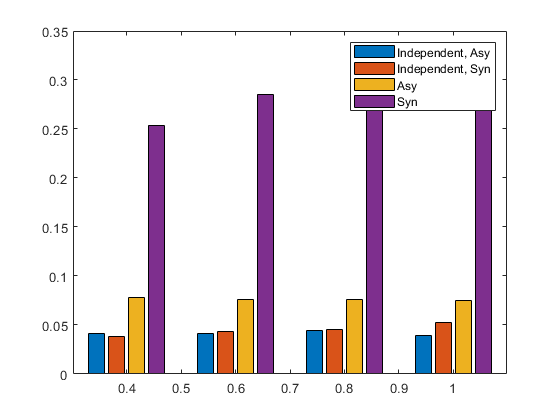

y = []; % it,j,ii
figure
for it = 1:numel(DeltaT_range)
    DeltaT = DeltaT_range(it);
    for j=1:2 % Asy OR Syn
        for ii = 1:2 %independent or not
            if ii==1
                load(['tempdata/TimeCost_Cordon_Pattern_Independent_',SynORAsy{j}, ...
                    '_n',num2str(n_range(end)),'_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
            else
                load(['tempdata/TimeCost_Cordon_Pattern_',SynORAsy{j}, ...
                    '_n',num2str(n_range(end)),'_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
            end
            y(it,j,ii) = t1;
        end
    end
end
legendstr = {'Independent, Asy','Independent, Syn','Asy','Syn'};
p = bar(1./DeltaT_range,reshape(y,numel(DeltaT_range),[]));
legend(legendstr);
hold off

## Figure: computer time VS (N*M)

M is the total time steps; N is the total building number

code:

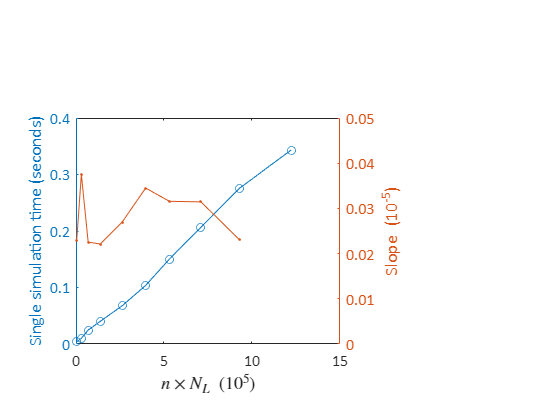

figure
SynORAsy = 'Syn'; 
x = n_range.^2;
y_asy = zeros(size(x));
y_syn = zeros(size(x));
for i=1:numel(n_range)
    load(['tempdata/TimeCost_Cordon_Pattern_',SynORAsy,'_n',num2str(n_range(i)), ...
        '_dt',num2str(DeltaT),'_P',num2str(P),'.mat']);
    M = zeros(1,numel(FShistCell));
    for i_eq = 1:numel(FShistCell)
        M(i_eq) = min([find(all(FShistCell{i_eq}==2,1),1),MaxT/DeltaT]);
    end
    x(i) = x(i)*mean(M);
    y_syn(i) = t1;
end

yyaxis left
plot(x./10^5,y_syn,'Marker','o');
box on
ax = gca; 
ax.FontSize = 12;
ax.FontName = 'Calibri';
ax.Units = "centimeters";
ax.Position = [2 2 7 6];
ax.PositionConstraint = "innerposition";
ylabel('Single simulation time (seconds)');
xlabel('$n\times N_{L}\ (10^{5})$','Interpreter','latex');

yyaxis right
plot(x(1:end-1)./10^5,(y_syn(2:end)-y_syn(1:end-1))./(x(2:end)-x(1:end-1)).*10^5,'Marker','.');
ylabel('Slope (10^{-5})');
ylim([0,0.05]);